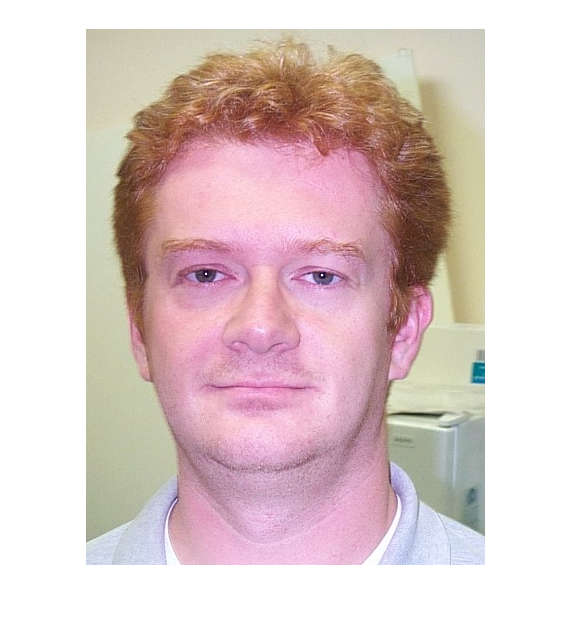

clearvars
inImage = imread('images\DB1\db1_02.jpg');
inImage = im2double(inImage);
originalImage = inImage;
imshow(originalImage);

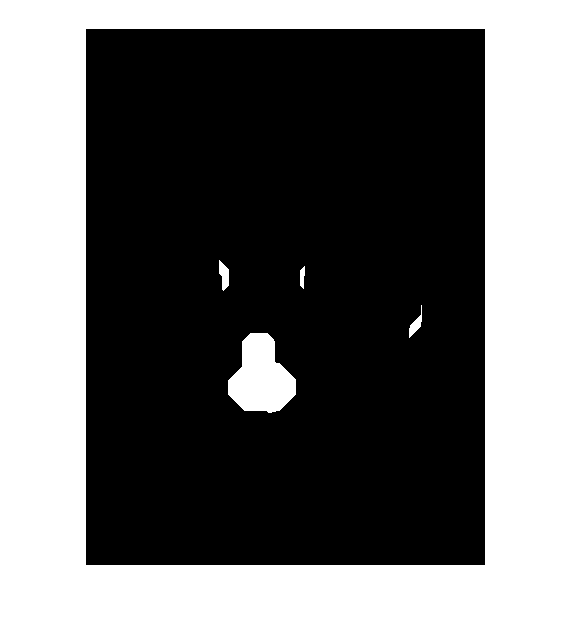


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%----Automatic White Balancing (AWB)----%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
inImage = AWB_max(inImage);
%imshow(inImage);

[mouthMap, centroid] = createMouthMap(inImage);
imshow(mouthMap);

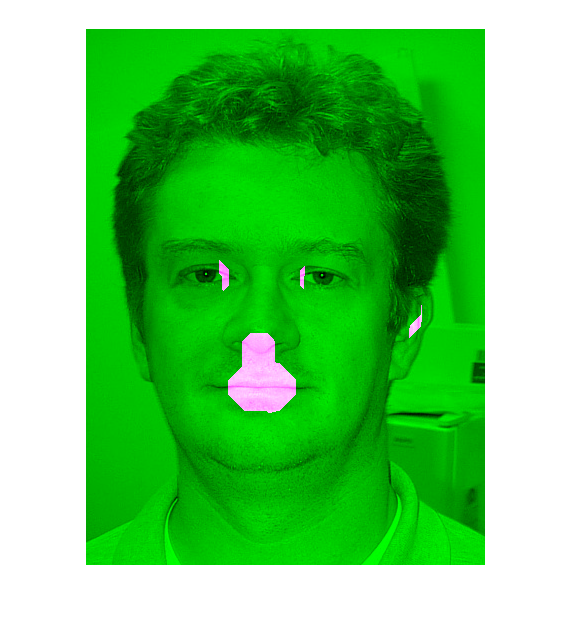

 
%Check result
C = imfuse(originalImage,mouthMap,'falsecolor','Scaling','independent'); imshow(C)

%imshow(im);

%faceMask = skinDetection(inImage);